g_o = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), zeros(3, 1));
%g_oA = SE3(eul2rotm([0, -pi/6, 0], 'xyz'), [0; 0.05; 0]);
g_oA = SE3(eye(3), [0; 0.05; 0]);
g_A = g_o * g_oA;

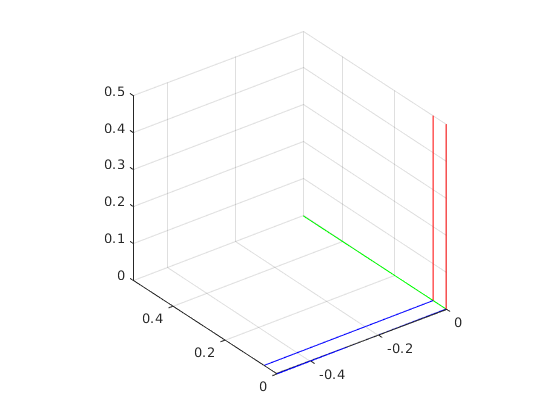

fig = figure();
ax = axes(fig);

plot_SE3({g_o, g_A}, ax)
grid on
axis equal

muscle_o = Muscle3D(0.1, zeros(3, 1), "adjoint_X_o",eye(4), 'g_0', g_o, "color", 'k');
muscle_A = Muscle3D(0.1, zeros(3, 1), "adjoint_X_o",ad_se3(inv(g_oA)), 'g_0', g_A, 'color', 'b');
muscles = [muscle_o muscle_A];

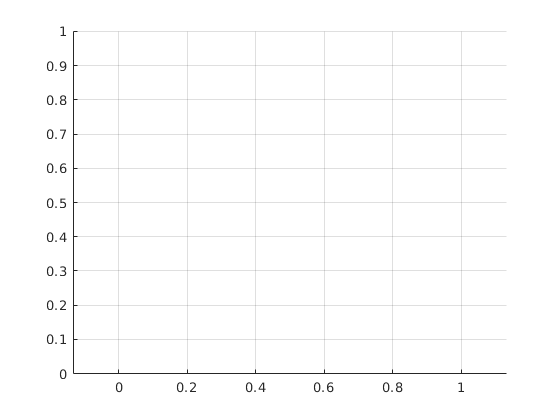

fig = figure();
ax = axes(fig);
grid on
axis equal

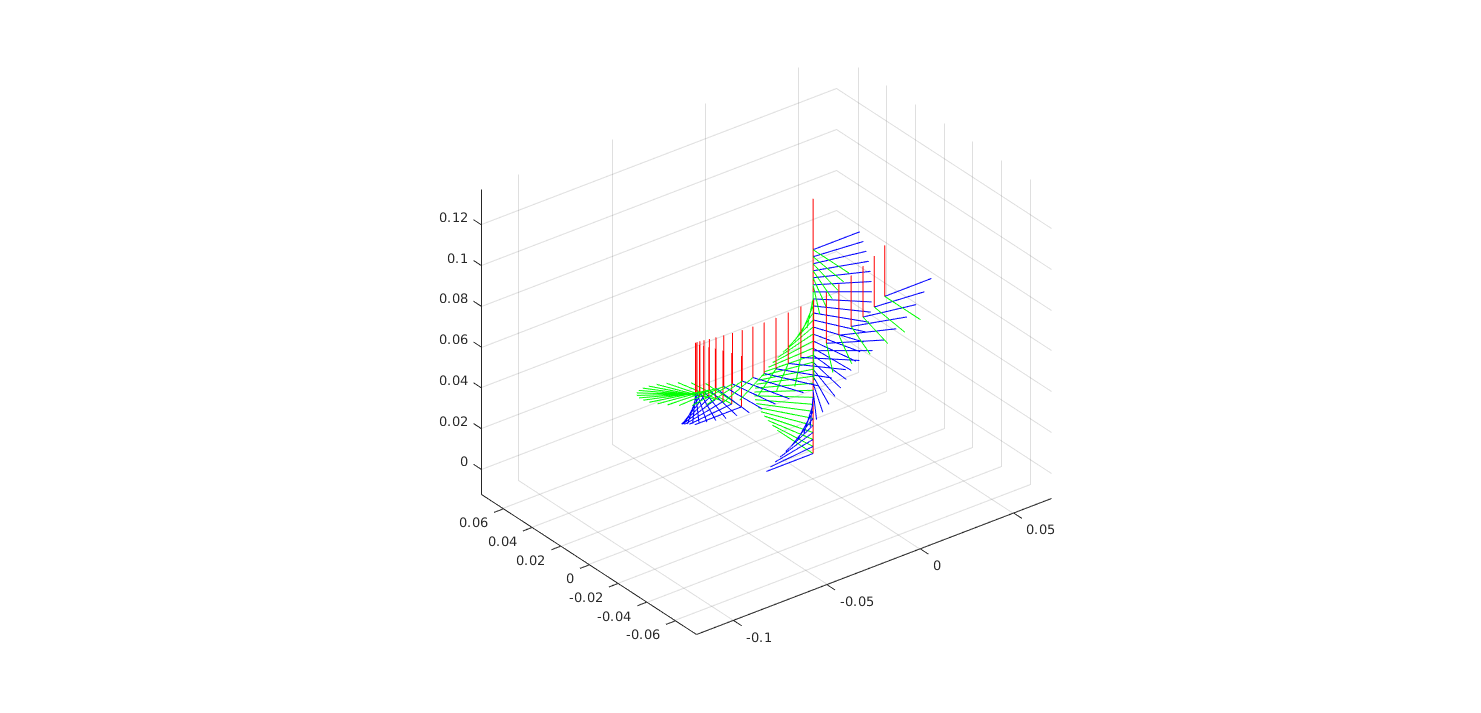

plot_options = struct('framesize', 0.025);

muscle_o.kappa = [pi / muscle_o.l; 0; 0];
muscle_A.h_tilde = muscle_A.adjoint_X_o * muscle_o.h_tilde;

if exist('v_gh', 'var')
    delete(v_gh)
end

v_gh = [];
g_muscles = cell(size(muscles));
for i = 1 : length(muscles)
    [gh_i, g_muscle_i] = muscles(i).plot_tforms(ax, 'resolution', 30, 'plot_options', plot_options);
    v_gh = [v_gh gh_i];
    g_muscles{i} = g_muscle_i;
end
set(fig, 'Position', [87, 81, 1481, 713])

function plot_SE3(gs, parent)
for i = 1 : length(gs)
    g_i = gs{i};
    plotTransforms(g_i(1:3, 4)', rotm2quat(g_i(1:3, 1:3)), 'parent', parent, 'framesize', 0.5);
end
end